% Panel A: network overview made in AI
addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project1--small-spiking-neural-network'))
addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
clear all

% "Baseline with random seeds"
% contains networks generated with fixed CTX connectivity as well as the
% fixed VPM input. so, multiple repetitions (i.e., rep1-5) are actually
% identical files.

% Load example data
load('/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Simulations/Baseline/Fig4_Net__VPM_seed97_CTX_seed70.mat')

% Analyse example data
SNN_analysed = analyzeSim(SpikingNetwork);

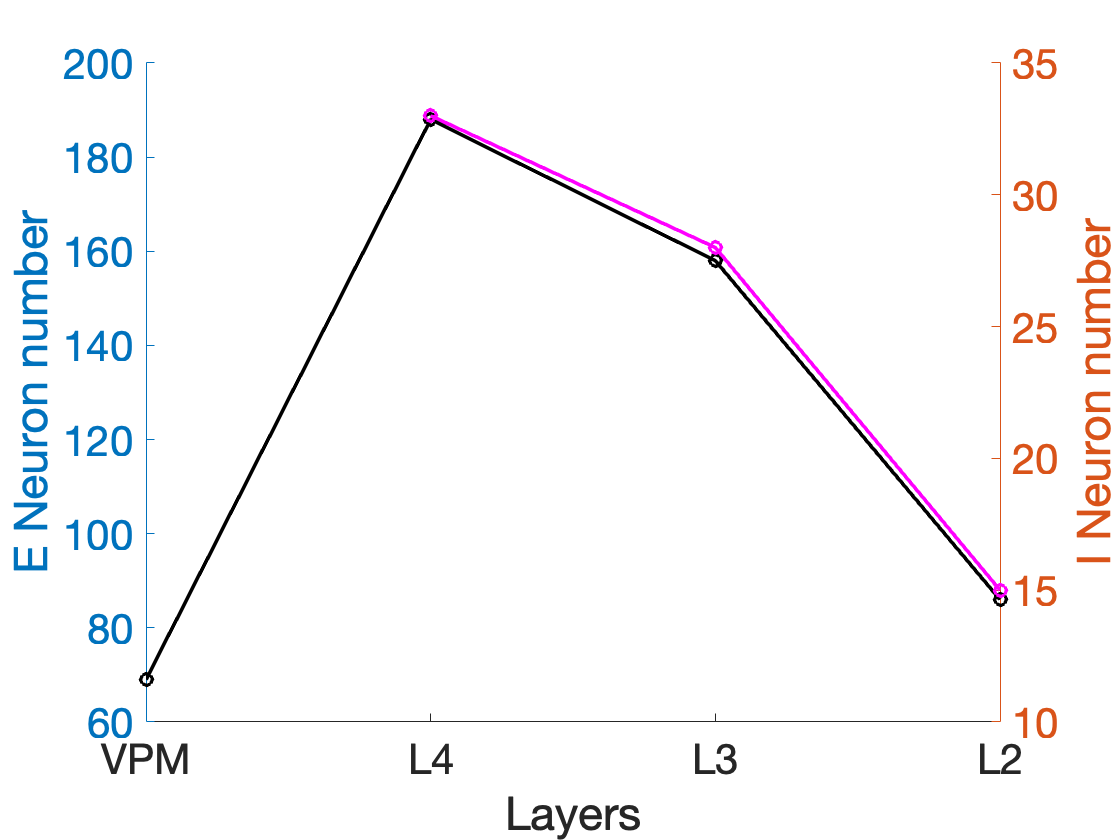

% number of cells per layer
figure; hold on;
cellNums = cell2mat(cellfun(@(x) length(x), SNN_analysed.spike_times, 'uniformoutput', false));
layers = [2 3 4 5];
eCells = [cellNums(2:2:end)' cellNums(end)];
iCells = [cellNums(1:2:end-1)'];

yyaxis left
plot(layers,eCells,'-ok','linewidth',1.8)
yax=gca;
yax.XTickMode = 'manual';
yax.XTick = layers;
yax.XTickLabels = ["L2","L3","L4","VPM"];
yax.XDir = 'reverse';
ylabel('E Neuron number')

yyaxis right
plot(layers(1:end-1),iCells,'-om','linewidth',1.8)
yax=gca;
yax.XTickMode = 'manual';
yax.XTick = layers;
yax.XTickLabels = ["L2","L3","L4","VPM"];

yax.FontSize=21;
xlim([2 5])
xlabel('Layers')
ylabel('I Neuron number')

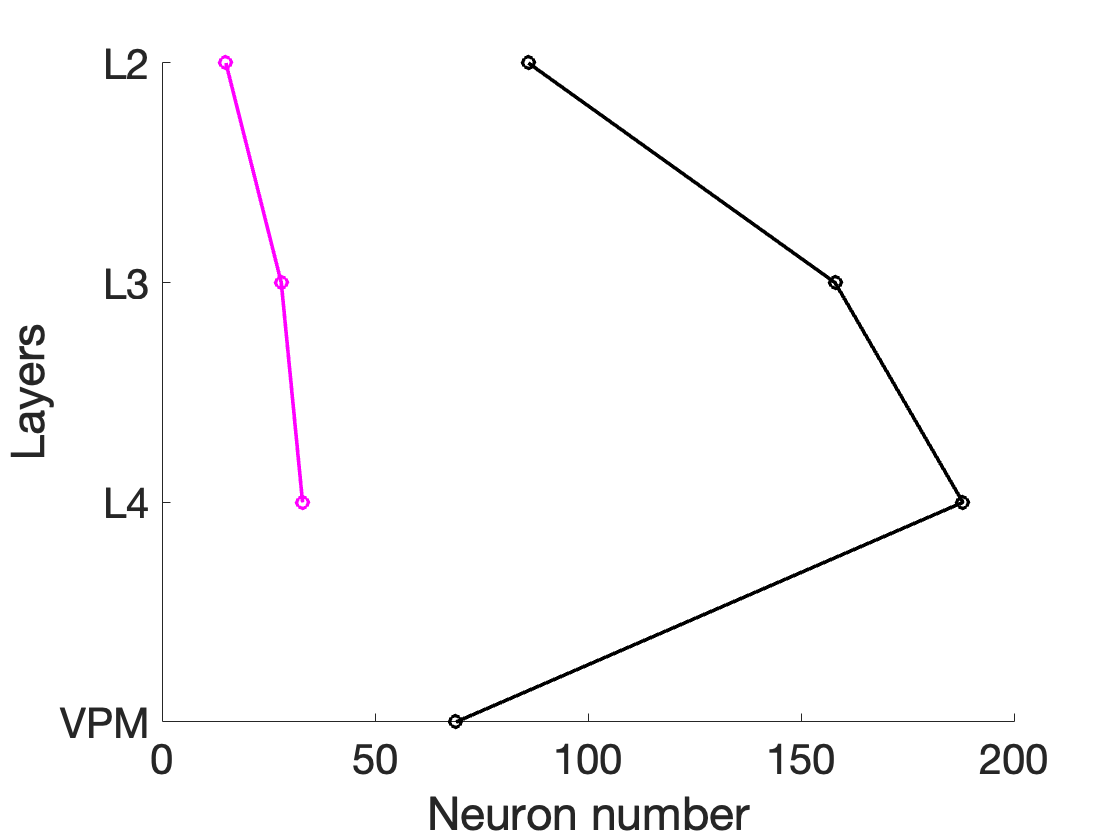


% alternative
% number of cells per layer
figure; hold on;
cellNums = cell2mat(cellfun(@(x) length(x), SNN_analysed.spike_times, 'uniformoutput', false));
layers = [2 3 4 5];
eCells = [cellNums(2:2:end)' cellNums(end)];
iCells = [cellNums(1:2:end-1)'];
plot(eCells,layers,'-ok','linewidth',1.8)
plot(iCells,layers(1:end-1),'-om','linewidth',1.8)
yax=gca;
yax.YTickMode = 'manual';
yax.YTick = layers;
yax.YTickLabels = ["L2","L3","L4","VPM"];
yax.YDir = 'reverse';
yax.FontSize=21;
ylim([2 5])
ylabel('Layers')
xlabel('Neuron number')

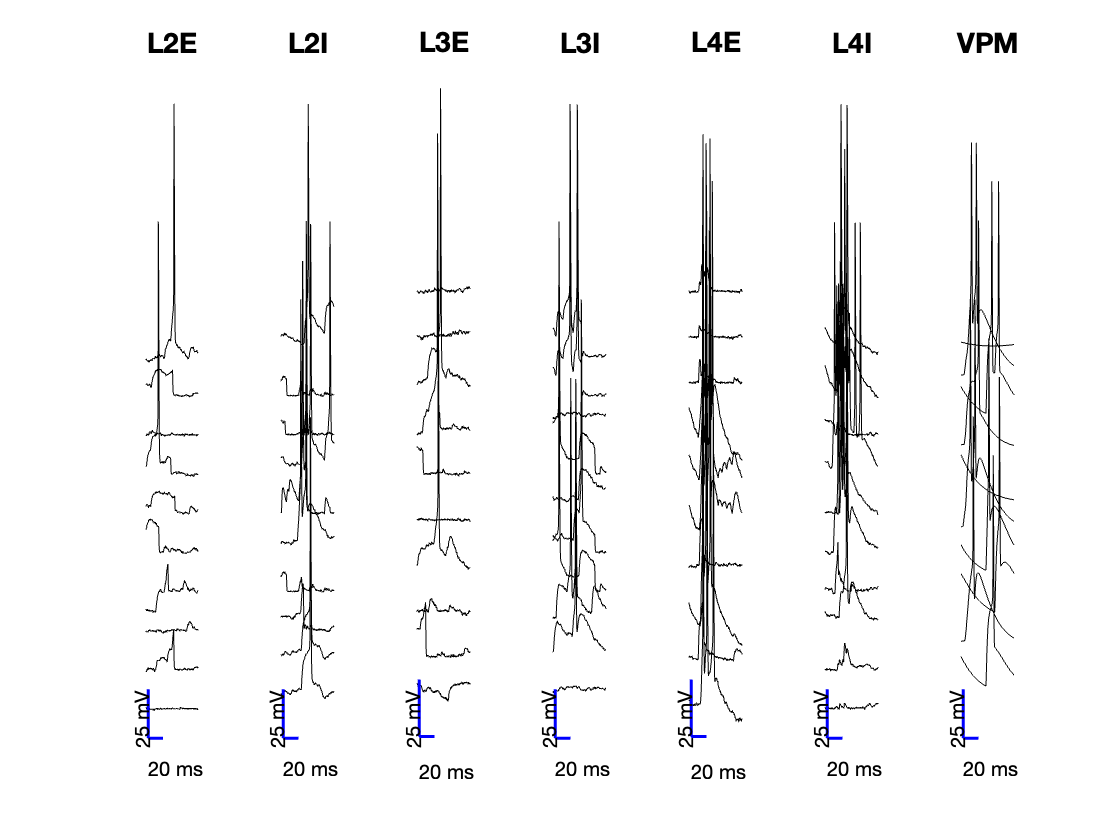

% Panel B: example membrane potential traces

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];
time = [SpikingNetwork.time(1) SpikingNetwork.time(end) SpikingNetwork.simulator_options.dt];
fullTime = time(1):time(3):time(2);

figure; clf;
tiledlayout(1,length(pops))

xlim1 = 330; % in ms, start time to show example signal traces
xlim2 = 400; % in ms, end time to show example signal traces

NumberOfNeurons = 10;

for pIdx = 1:length(pops)-1
    nexttile; hold on;
    yAxisSpread = (0:NumberOfNeurons-1)*20;
    neuronIdx = randi(size(SpikingNetwork.([pops(pIdx,:) '_V']),2),NumberOfNeurons,1);
    plot(repmat(fullTime,NumberOfNeurons,1)',...
        SpikingNetwork.([pops(pIdx,:) '_V'])(:,neuronIdx)+yAxisSpread,'color','k')
    xlim([xlim1 xlim2])
    axis off; box off;
    line([xlim1+3 xlim1+3],[-95 -70],'linewidth',1.5,'color','b')
    line([xlim1+3 xlim1+23],[-95 -95],'linewidth',1.5,'color','b')
    text(xlim1-5, -100, '25 mV','rotation',90)
    text(xlim1+3, -110, '20 ms','rotation',0)
    
    title(pops(pIdx,:), 'fontsize', 14)
end

nexttile; hold on;
try
    combinedVPMpops = [SpikingNetwork.VPMcorr_V SpikingNetwork.VPMuncorr_V];
catch ME
    combinedVPMpops = SpikingNetwork.VPM_V;
end
combinedVPMpops=combinedVPMpops(:, randperm(size(combinedVPMpops, 2)));
plot(repmat(fullTime,NumberOfNeurons,1)',combinedVPMpops(:,randi(size(combinedVPMpops,2),NumberOfNeurons,1))+yAxisSpread,'color','k')
xlim([xlim1 xlim2])
axis off; box off;
line([xlim1+3 xlim1+3],[-95 -70],'linewidth',1.5,'color','b')
line([xlim1+3 xlim1+23],[-95 -95],'linewidth',1.5,'color','b')
text(xlim1-5, -100, '25 mV','rotation',90)
text(xlim1+3, -110, '20 ms','rotation',0)
title('VPM', 'fontsize', 14)

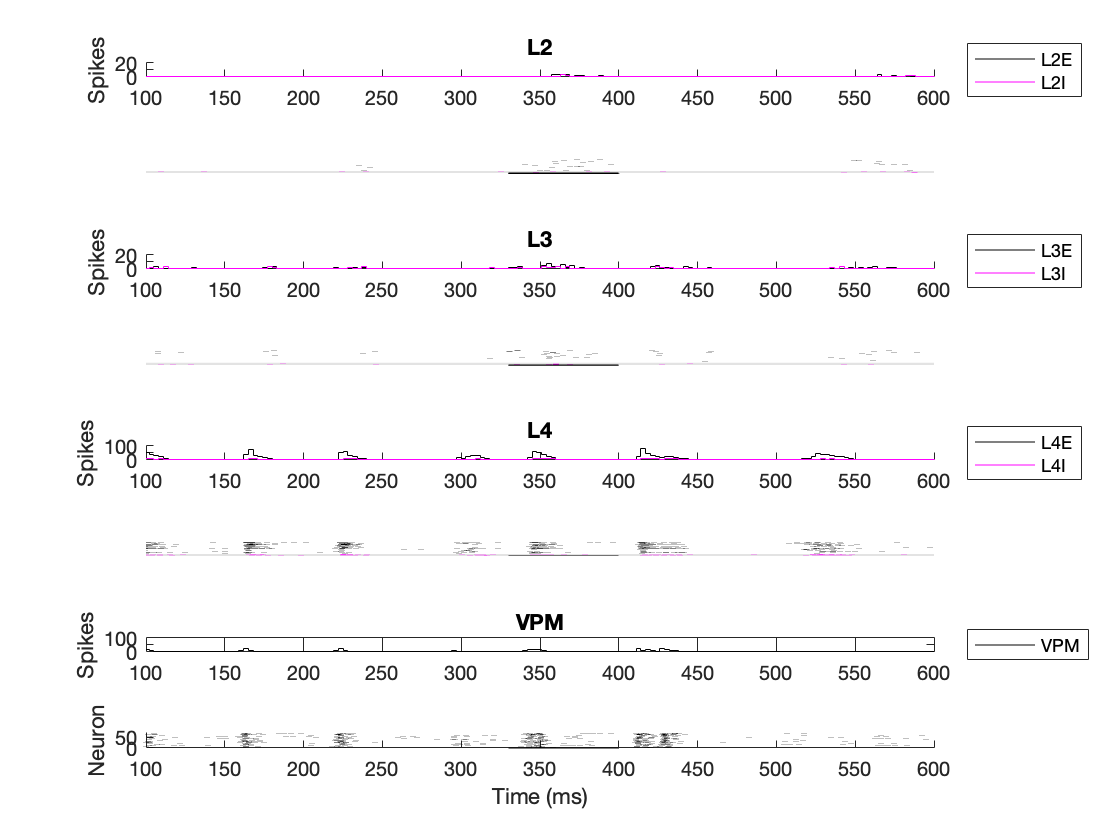

% Panel C: rasters and PSTHs
clearvars -except SpikingNetwork SNN_analysed xlim1 xlim2

cutStartTime =  100;
pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];
time = [SpikingNetwork.time(1) SpikingNetwork.time(end) SpikingNetwork.simulator_options.dt];
fullTime = time(1):time(3):time(2);
figure; clf;
tiledlayout(8,1)

binSize = 3;
ylim2_l4e = 100;

pcol1 = 'k';        % excitatory color
pcol2 = 'm';        % inhibitory color
pcol3 = 'k';%colormap(summer(1));

for pIdx = 1:2:length(pops)-1
    if ismember(pIdx,[1 3])
        ylim2=floor(ylim2_l4e/5);
    else
        ylim2=ylim2_l4e;
    end
    nexttile; hold on;
    plotPsthAndRaster('psth',getSpikeTimes(SpikingNetwork.([pops(pIdx,:) '_V']),[time(1):time(3):time(2)]),binSize,time(2),1, pcol1);
    plotPsthAndRaster('psth',getSpikeTimes(SpikingNetwork.([pops(pIdx+1,:) '_V']),[time(1):time(3):time(2)]),binSize,time(2),1, pcol2);
    xlim([cutStartTime time(2)])
    ylim([0 ylim2])
    ylabel('Spikes')
    title(pops(pIdx,[1 2]))
    
    legend({pops(pIdx,:); pops(pIdx+1,:)}, 'location', 'eastoutside')
    
    nexttile; hold on;
    eNum = size(SpikingNetwork.([pops(pIdx,:) '_V']),2);
    iNum = size(SpikingNetwork.([pops(pIdx+1,:) '_V']),2);
    yyaxis left
    plotPsthAndRaster('raster',getSpikeTimes(SpikingNetwork.([pops(pIdx,:) '_V']),[time(1):time(3):time(2)]),1,time(2),1,pcol1);
    ylim([-iNum eNum])
    xlim([cutStartTime time(2)])
    rectangle('position',[cutStartTime, -iNum, time(2), iNum], 'facecolor', '#E3E3E3', 'edgecolor','none')

    yyaxis right
    plotPsthAndRaster('raster',getSpikeTimes(SpikingNetwork.([pops(pIdx+1,:) '_V']),[time(1):time(3):time(2)]),1,time(2),1,pcol2);
    ylim([0 iNum+eNum])
    xlim([cutStartTime time(2)])
    axis off
    rectangle('position',[xlim1, -3, xlim2-xlim1, 3]) % [x y w h] in data units
end

nexttile; 
try
    combinedVPMpops = [SpikingNetwork.VPMcorr_V SpikingNetwork.VPMuncorr_V];
catch ME
    combinedVPMpops = SpikingNetwork.VPM_V;
end
combinedVPMpops=combinedVPMpops(:, randperm(size(combinedVPMpops, 2)));
plotPsthAndRaster('psth',getSpikeTimes(combinedVPMpops,[time(1):time(3):time(2)]),binSize,time(2),1,pcol3);
xlim([cutStartTime time(2)])
ylim([0 ylim2])
ylabel('Spikes')
legend("VPM", 'location', 'eastoutside')
title(pops(end,:))

nexttile; hold on;
plotPsthAndRaster('raster',getSpikeTimes(combinedVPMpops,[time(1):time(3):time(2)]),1,time(2),1,pcol3);
ylim([0 size(combinedVPMpops,2)])
xlim([cutStartTime time(2)])
% axis off
rectangle('position',[xlim1, -0.5, xlim2-xlim1, 0.5])
xlabel('Time (ms)')
ylabel('Neuron')

% Panel C: data
AnalysisPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Analysis/Baseline/Baseline_analysis';

cd(AnalysisPath)
a = load('BaselineDatasetAnalysis_pt1.mat');
load('BaselineDatasetAnalysis_pt2.mat');
SNN_analysed = [a.SNN_analysed; SNN_analysed];
clear a

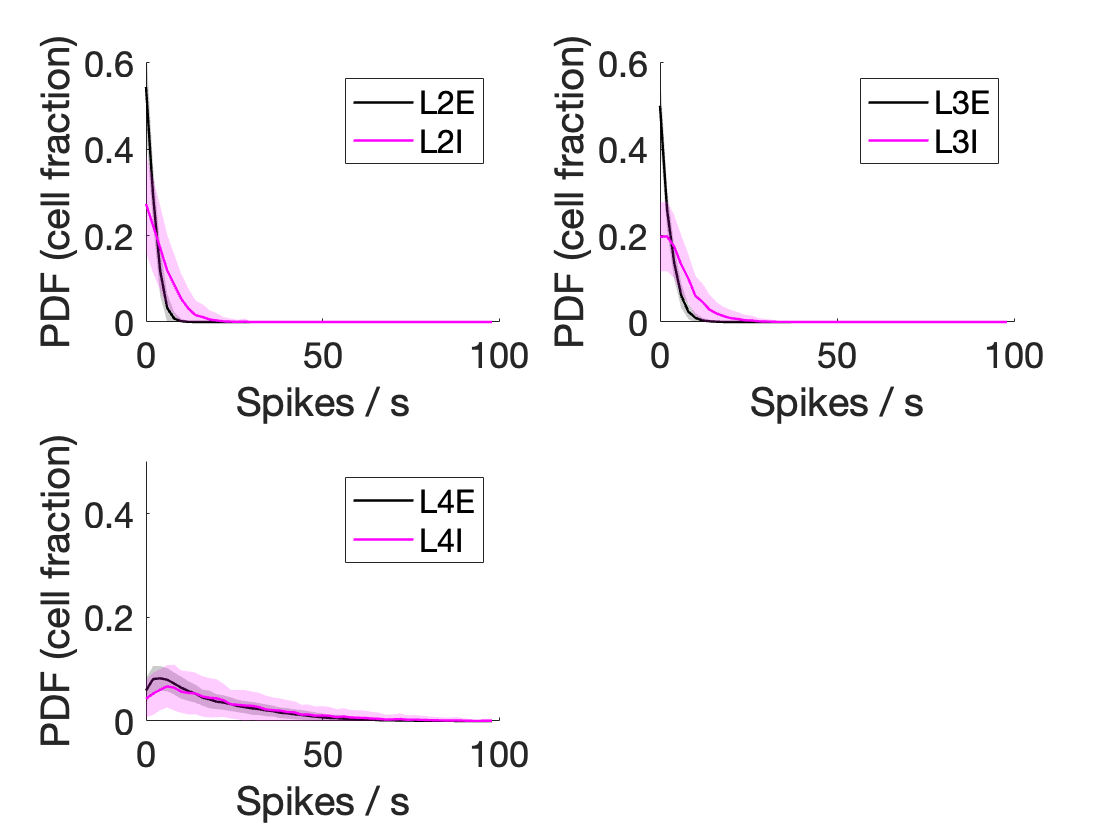

% Panel C: FR PDF
clearvars -except SNN_analysed

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I';'VPM'];
figure; clf; tiledlayout(2,2)

maxFR = 100;
hist_bins = [0:2:maxFR];

for jj=1:6 % populations
    dataFiltered = [];
    instFR = [];
    if jj == 7
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, 'VPM'),:);
    else
        tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)),:);
    end
    cellNum = length(tbl.SpikeTimes{1,1});
    data = tbl.SpikesPerSec;
    dataHist = [];
    
    for kk=1:length(data)
        miniData = cell2mat(data{kk, 1});
        miniData(isnan(miniData)) = 0;
        dataHist{kk,1} = histcounts(miniData,hist_bins)/sum(histcounts(miniData,hist_bins));
    end

    if rem(jj,2)~=0
        col = 'k'; % excitatory
        nexttile; hold on;
    else
        col = 'm'; % inhibitory
    end
    
    % plot mean of all histograms with std as variance (shade)
    stdShade(cell2mat(dataHist),0.2,col,hist_bins(1:end-1))
    
    if rem(jj,2)==0
        xlim([0 maxFR])
        ylim([0 0.6])
        xlabel('Spikes / s')
        ylabel('PDF (cell fraction)')
        set(gca,'fontsize',18)
        ax=get(gca,'Children');
        legend(flipud(ax(1:2:end)),pops(jj-1,:), pops(jj,:))
    end
end
nexttile(3); ylim([0 0.5])